% clc;clear;
% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_samples.dat')

fid = 27

data = fread(fid,'short');

% cfg = getconfig();
% %%  ------ Baseband part
% bb=zeros(cfg.users,cfg.symbollen);
% 
% %get the sending he-ltf baseband for each user
% for u=1:1
%     [bb(u,:),cfg.userltf(u,:)]=getheltf(cfg,u);
% %     plot(real(bb(u,:)));
% %     hold on
% end

i = 1;
% symbollen_table = [288, 576, 1152];
% gilen_table = [32, 64, 128];
symbollen = cfg.symbollen;
gilen = cfg.gilen;

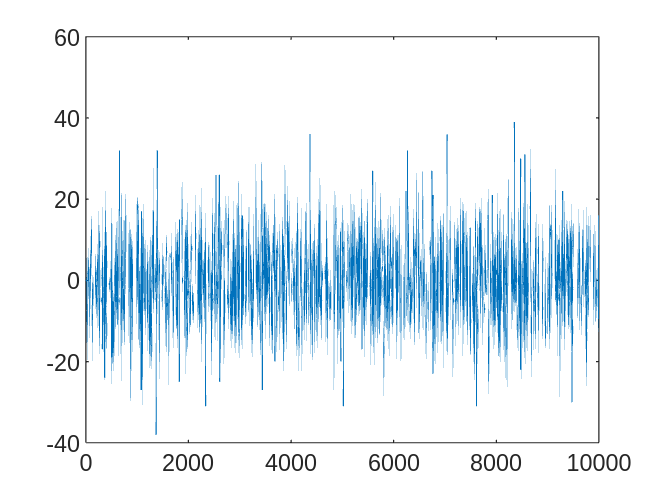

% time domain
plot(data(1:10000))
hold on


% freq domain
fs = 100e6; % sampling frequency

% Xdata = fft(data(1000:n));
% plot(abs(Xdata))
% 
% f = (0:n-1) * (fs/n); % frequency range
% power = abs(Xdata).^2/n;  % power
% CIR_data = fftshift(Xdata);
% plot(f, power)
% 
% Ydata = fftshift(Xdata);   
% fshift = (-n/2:n/2-1)*(fs/n);   % zero-centered frequency range 
% powershift = abs(Ydata).^2/n;   % zero-centered power
% plot(fshift,powershift)



% decode part 
Ydata = fftshift(fft(data(gilen+1:symbollen)))'

Ydata = 1.0e+02 *

   5.1300 + 0.0000i  -0.7623 + 0.4718i  -0.5553 + 0.1259i  -0.0708 + 1.6462i   2.6377 - 0.7707i   1.3209 - 0.7445i   0.0484 + 1.9656i   0.4867 + 0.5880i  -0.6588 - 0.7569i   2.1692 - 0.9904i   0.1027 - 0.5794i   2.2764 + 0.8077i  -0.8992 + 0.6621i   0.4404 + 1.9306i  -0.6765 + 1.5856i  -0.3075 - 0.3758i  -1.3971 + 1.8471i  -0.1565 + 0.1206i   1.2914 - 0.7425i  -2.5360 - 1.3107i  -0.7891 + 1.1838i   1.0794 - 1.1657i   1.7294 + 0.2308i   1.7552 + 1.9772i   0.9885 - 0.4397i   0.2891 + 0.4887i   2.6191 - 1.2058i   0.5246 - 0.0165i   0.0716 - 0.9525i  -0.2641 - 0.7110i  -1.9017 + 0.2499i  -0.5041 - 0.9534i   0.8358 + 0.7738i   1.8378 - 0.8057i  -1.0520 - 0.4756i   0.2669 - 0.3005i  -1.1556 - 2.6410i  -0.8944 - 0.3381i   2.9957 - 0.6552i   0.3240 - 1.0646i   1.3466 + 1.2075i   0.9808 + 0.2606i   0.6541 - 1.4910i   0.8399 + 0.4155i  -0.3241 + 0.2757i  -0.5450 - 0.8953i   1.7704 - 0.4328i   0.5863 + 0.3915i   0.7711 - 1.1507i  -1.8933 + 0.0460i


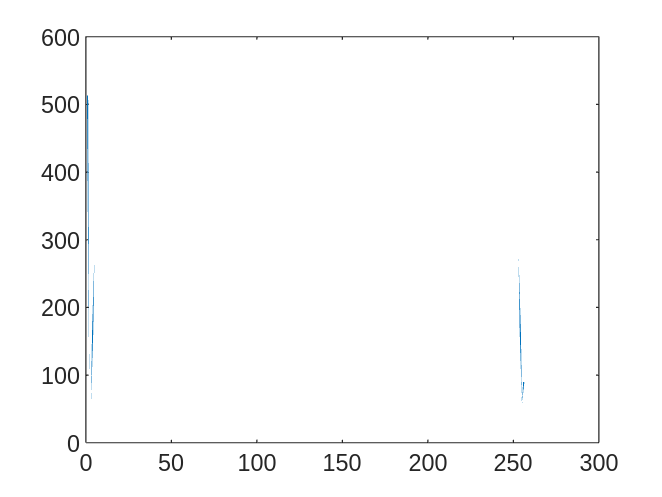

figure
plot(abs(Ydata))

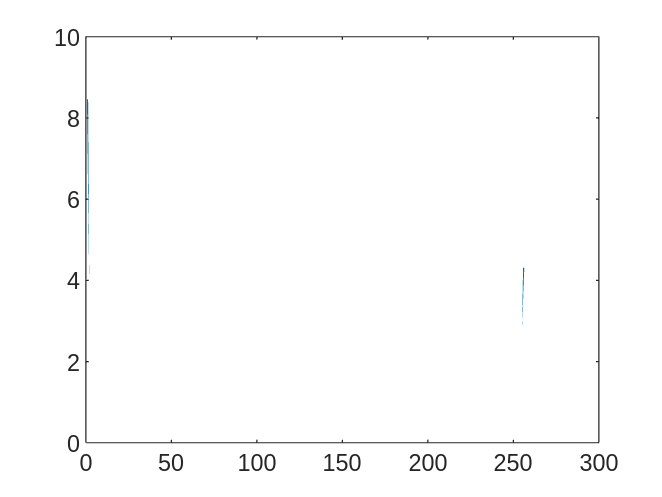

cir = zeros(cfg.users, cfg.fftlen);
cir(1,:) = ifft(fftshift(Ydata.*conj(cfg.userltf(1,:))));
plot(abs(cir(1,:)))
hold on



% 
% N = 100000;
% matlab_fft = figure;
% yfreq = fft(data)/N;
% f = (0:N-1) * 10/N;
% yfreq = yfreq*2;
% plot(f(1:N/2), abs(yfreq(1:N/2)));
% max(yfreq)
% 
% % data = read_complex_binary('b210_usrp_samples.dat');
% % 
% % plot([real(data), imag(data)]);
% plot(data);